# Plot Position Using GPS Connected to Arduino Hardware

This example shows how to get the geographic location using the GPS module connected on Arduino hardware and plot the location in a map.

## Required Hardware

To run this example, you need:

- Arduino Mega2560 

- UBlox Neo-6M GPS module

- GPS antenna

- USB cable

- Connecting wires

## Hardware Connections

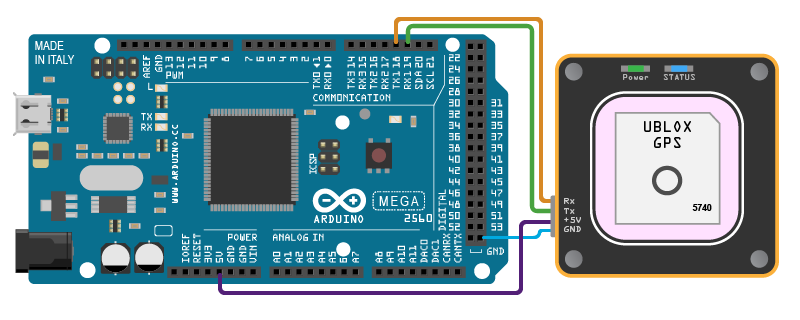

Connect the pins on the UBlox Neo-6M GPS module to the pins on your Arduino Mega 2560 board. The connections are: 

- +5V - 5V  

- GND - GND

- RX - TX1(pin 18)

- TX - RX1(pin 19)

Connect the GPS antenna to the GPS module. GPS Fix can be easily acquired in locations that have a clear view of the sky. Wait for the GPS module to acquire satellite signals(Fix).This can be verified by checking the Fix LED of your GPS module 

## Create GPS Object

Create an `arduino` object and include the Serial library.

a = arduino('COM6','Mega2560','Libraries','Serial');

Create the GPS sensor object.

gps = gpsdev(a)

## Read the GPS data

Read the GPS data and extract latitude, longitude, and time from it. 

gpsData = gps.read;
latitude = gpsData.LLA(1);
longitude = gpsData.LLA(2);
gpsTime = gpsData.GPSReceiverTime;
% GPS returns UTC datetime. Convert it into system time zone.
gpsTime.TimeZone = 'local';

## Plot the position in a map along with the timestamp

Plot the position in geographic axes with the data obtained from the GPS module. GPS should have fix to get valid values for latitude, longitude and `gpsTime`. 

If the GPS module does not have fix, the above commands give `NaN`s for latitude and longitude and `NaT` for `gpsTime`. In this case, make sure the antenna is exposed to clear sky and wait for some time and try the above steps again. 

if(~isnan(latitude) && ~isnan(longitude))
 % plot the position in geographic coordinates
 fig = geoplot(latitude,longitude,'Marker',"o",'MarkerSize',6,'Color','red','MarkerFaceColor','red');

 % Sets the latitude and longitude limits of the base Map   
 geolimits([latitude-0.05,latitude+0.05],[longitude-0.05,longitude+0.05]) ;

 % Selects the basemap   
 geobasemap streets;
 timeString = strcat("Timestamp: ",string(gpsTime));

 % Create annotation and display time received from GPS
 annotation('textbox', [0.005, 0.98, 0.6, 0.01], 'FitBoxToText','on','string', timeString,'Color','blue','FontSize',10);
end

## Clean Up

When the connection is no longer needed, clear the associated object.

delete(gps);
clear gps;
clear a;

*Copyright 2020 The MathWorks, Inc.*